# Steady state initialization of an optimal control problem

## I) Introduction

We consider the following optimal control problem (Hypersensitive problem from [1])

$\min \;J=\int_0^T \left\lbrack {x\left(t\right)}^2 +{u\left(t\right)}^2 \right\rbrack \cdot \textrm{dt}$    (1)

$\dot{\frac{\textrm{dx}\left(t\right)}{\textrm{dt}}=-{x\left(t\right)}^3 +u\left(t\right)}$                  (2)

$x\left(0\right)=x_0$ and $x\left(T\right)=x_T$            (3)

Numerical application : $T={10}^4$, $x_0 =1$ and $x_T =1\ldotp 5$

We intend to apply a continuation procedure starting from a small $T$ value $\left(T={10}^2 \right)$until thevalue of interest $\left(T={10}^4 \right)$.

To do so, we reformulate the problem so that it can be solved over a normalized time interval $\left\lbrack 0,1\right\rbrack$using a simple change of variable $t=T\cdot \alpha$ with $\alpha$ the new time variable.

$\min \;J=\int_0^1 \left\lbrack {x\left(\alpha \right)}^2 +{u\left(\alpha \right)}^2 \right\rbrack \cdot T\cdot d\alpha$    (4)

$\dot{\frac{\textrm{dx}\left(t\right)}{d\alpha }=\left\lbrack -{x\left(t\right)}^3 +u\left(\alpha \right)\right\rbrack \cdot T}$                  (5)

$x\left(0\right)=x_0$ and $x\left(1\right)=x_T$                    (6)

Let $p$ be the costate. The Hamiltonian associated with this problem is:

$H=$$\left\lbrack {x\left(\alpha \right)}^2 +{u\left(\alpha \right)}^2 \right\rbrack \cdot T+p\left\lbrack -{x\left(\alpha \right)}^3 +u\left(\alpha \right)\right\rbrack \cdot T$    (7)

The optimal control is solution of $H_u =0$:

$\frac{\partial H}{\partial u}=2Tu\left(\alpha \right)+\textrm{pT}=0\iff u\left(\alpha \right)=-\frac{p}{2}$             (8)

The optimal costate dynamics is:

$\frac{\textrm{dp}\left(\alpha \right)}{d\alpha }=-H_x =T\cdot \left\lbrack -2x\left(\alpha \right)+3{x\left(\alpha \right)}^2 \right\rbrack$                (9)

Let us denote $z\left(\alpha \right)={\left(x\left(\alpha \right),p\left(\alpha \right)\right)}^T$. Then the BVP to be solved is:

$\left\lbrace \begin{array}{l}
\frac{\textrm{dz}\left(\alpha \right)}{d\alpha }=\left\lbrack \begin{array}{c}
-{x\left(t\right)}^3 \cdot T-\frac{p}{2}\cdot T\\
-2\cdot T\cdot x\left(\alpha \right)+3\cdot T\cdot {x\left(\alpha \right)}^2 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
x\left(0\right)-x_0 \\
x\left(1\right)-x_T 
\end{array}\right\rbrack =0
\end{array}\right.$            (10)

clearvars
close all
clc

### Problem parameters

x0=1;xT=1.5;

### Define continuation procedure parameters

paramStart.T=1e2;paramEnd.T=1e4;
fixedParams.x0=x0;fixedParams.xT=xT;

## II) Constant initial solution

To perform a continuation procedure from $T={10}^2$ to $T={10}^4$, we need an initial solution for $T={10}^2$. Let us try a constant solution 

xInit=1.25;pInit=0;T=paramStart.T;
nInit=1000;
solInit.x=linspace(0,T,nInit);
solInit.y=repmat([xInit;pInit],[1 nInit]);

We can now define the problem to be solved at each iteration of the continuation procedure. It consists in the boundary value problem (12) & (13). This BVP will be solved using Matlab bvp5c solver.

We also need several functions (available at the bottom of this document):

- generateFodeFcn : to generate a handle to the BVP dynamics that uses the current value of the continuation parameters

- generateBCFcn : to generate a handle to the BVP boundary conditions that uses the current value of the continuation parameters

bvpOpt=bvpset('RelTol',1e-3,'AbsTol',1e-6,'Nmax',50000);
problem=bvp4or5c('bvp5c',@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt);

Let us check that the BVP is not solvable with this initial guess:

try        
    sol=problem.solveProblem(solInit,paramStart,fixedParams);
    originalBVPsolved=true;
catch Error
    originalBVPsolved=false;
    fprintf('The problem was not solved using a standard bvp solver\n')
end

The problem was not solved using a standard bvp solver


if originalBVPsolved
    error('Original bvp was sucessfully solved')
end

## III) Compute a valid initial solution

We first need to compute a control value $u_{\textrm{ss}}$ and a state value $x_{\textrm{ss}}$ such that the system is at steady state.

 
$$\dot{\frac{\textrm{dx}\left(t\right)}{d\alpha }=0\iff \left\lbrack -{x_{\textrm{ss}} }^3 +u_{\textrm{ss}} \right\rbrack \cdot T=0\iff u_{\textrm{ss}} ={x_{\textrm{ss}} }^3 }$$


Let us arbitrarily chose $x_{\textrm{ss}} =\frac{x_0 +x_T }{2}$

Xss=(x0+xT)/2;Uss=Xss^3;

We can now compute an initial solution automatically using an `OCPsteadyStateInitialization` object. Using a large number of points in the initial solution ease the computation of the solution.

fprintf('Computing a valid initial solution\n')

Computing a valid initial solution


ocp=OCPsteadyStateInitialization(problem,Xss,1,'fixedParams',fixedParams,'targetParams',paramStart,'nInit',100);
solInit=ocp.run;

Initial solution is supposed feasible
 - Iter : 001 Lambda : 1.0000e+00 delta : 1.00e-01
   => MATLAB:bvp5c:SingJac:Unable to solve the collocation equations -- a singular Jacobian encountered 
 - Iter : 002 Lambda : 9.1667e-01 delta : 8.33e-02
   => MATLAB:bvp5c:SingJac:Unable to solve the collocation equations -- a singular Jacobian encountered 
 - Iter : 003 Lambda : 9.3056e-01 delta : 6.94e-02
   => MATLAB:bvp5c:SingJac:Unable to solve the collocation equations -- a singular Jacobian encountered 
 - Iter : 004 Lambda : 9.4213e-01 delta : 5.79e-02
   => MATLAB:bvp5c:SingJac:Unable to solve the collocation equations -- a singular Jacobian encountered 
 - Iter : 005 Lambda : 9.5177e-01 delta : 4.82e-02
   => MATLAB:bvp5c:SingJac:Unable to solve the collocation equations -- a singular Jacobian encountered 
 - Iter : 006 Lambda : 9.5981e-01 delta : 4.02e-02
 - Iter : 007 Lambda : 9.1159e-01 delta : 4.82e-02
 - Iter : 008 Lambda : 8.5372e-01 delta : 5.79e-02
 - Iter : 009 Lambda : 7.8427

fprintf('An initial solution has been obtained\n');

An initial solution has been obtained


## IV) Continuation procedure

Now we have a valid initial solution, we can perform the continuation procedure to bring the final time $T$ to its final value $T={10}^4$.

We use a custom function `plotFigFcn` to plot the solution at every iteration and we request to modify the solution provided by the BVP solver.  We also use `preIterPrintFcn` to display the value of `a` and `rho` at every iteration.

plotFigFcn : to plot the solution obtained at every iteration

modifySolutionFcn : function to add the control `u` and the Hamiltonian `H` to the solution.

`preIterPrintFcn``: `function to display the value of `T `at every iteration 

Let us first create a linear scheduler:

scheduler=linearScheduler(paramStart,paramEnd, fixedParams=fixedParams,...
    initialDelta=0.1,beta=1.2,deltaMin=1e-10,lambdaMin=1e-10);

Finally, we can run the continuation procedure.

fprintf('Continuation procedure on T\n')

Continuation procedure on T


Checking initial solution feasability
Done (initial solution is feasible)
Iter : 001 Lambda : 1.0000e+00 delta : 1.00e-01 T=Iter : 002 Lambda : 8.8000e-01 delta : 1.20e-01 T=Iter : 003 Lambda : 7.3600e-01 delta : 1.44e-01 T=Iter : 004 Lambda : 5.6320e-01 delta : 1.73e-01 T=Iter : 005 Lambda : 3.5584e-01 delta : 2.07e-01 T=Iter : 006 Lambda : 1.0701e-01 delta : 2.49e-01 T=Iter : 007 Lambda : 1.0000e-10 delta : 2.99e-01 T=

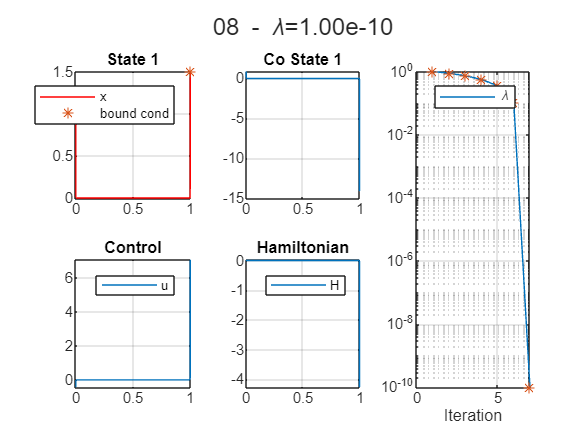

cont=continuationProcedure(problem,scheduler,solInit, ...
    "plotFigFcn",@plotFigFcn,...
    "modifySolutionFcn",@modifySolutionFcn,...
    "preIterPrintFcn",@preIterPrintFcn);
cont.run;

fprintf('Problem sucessfully solved\n')

Problem sucessfully solved


## IV) Additionnal code

### Function related to the BVP to be solved

This code allows to compute the solution of the Hamiltonian minimization

function [u,H]=computeControlHamiltonian(x,p,T)
% Compute the optimal control u and the hamiltonian (if requested)
u=-p/2;
if nargout==2
    % Only compute the Hamiltonian when requested
    H=T*((x.^2+u.^2)+p.*(-x.^3+u));
end
end

he BVP dynamics is given here. It depends on several parameters  whose value wil be passed by the `generateFode` function.

function dydt=fdyn(y,T)
% Compute the BVP to be solved : dYdt=[dxdt;dpdt]
x=y(1);p=y(2);
% Compute the control
[u,~]=computeControlHamiltonian(x,p,T);
% Compute state & co-state dynamics
dxdt = T*(-x.^3+u);
dpdt = T*(3*p*x^2-2*x);
dydt=[dxdt;dpdt];
end

This is the code for the boundary value problem.

function res=bcfun(ya,yb,x0,xT)
% Boundary condition to be canceled
res=[(ya(1)-x0);
    (yb(1)-xT)];
end

### Functions specific to the continuation procedure

- **generateFodeFcn**

`generateFodeFcn` has to provide a handle to the bvp dynamics according to the parameter values (manipulated or not by the continuation procedure). Here the `rho` parameter will be updated by the continuation procedure while `a`, `umin` and `umax` are fixed. 

function fode=generateFodeFcn(continuationParams,fixedParams)
% retrieve a handle to the ode function with the current parameters
% values
retrieveContinuationParameters({continuationParams,fixedParams});
fode=@(t,y) fdyn(y,T);
end

- `generateBCFcn`

`generateBCFcn` has to provide a handle to the bvp boundary conditions according to the parameter values (manipulated or not by the continuation procedure).  In this example `x0` and `xT` remains fixed.

function bcond=generateBCFcn(continuationParams,fixedParams)
% retrieve a handle to the boundary condition function with the
% current parameters values
retrieveContinuationParameters({continuationParams,fixedParams});
bcond=@(ya,yb) bcfun(ya,yb,x0,xT);
end

- `modifySolutionFcn`

In the optimal control problem, the controls $u$ is computed but it remains an internal data usined internaly within the BVP dynamics `fdyn`. As we would like to display the controls signal, we need to add it to the solution structure. We also compute the Hamiltonian value in the same way. 

function sol=modifySolutionFcn(sol,iterSuccess,continuationParams,fixedParams)
if iterSuccess
    retrieveContinuationParameters({continuationParams,fixedParams});
    x=sol.y(1,:);p=sol.y(2,:);
    % Add the control signal u to the solution
    [sol.u,sol.H]=computeControlHamiltonian(x,p,T);
end
end

- `plotFigFcn`

The `plotFigFcn` receive an `iterartiveDisplay` object that allows quick update of the graphics. It is advised to use it. The continuation procedure will call the `id.newIteration` and the `id.finalIteration` methods.

Alternatively, you may use your own code. The `plotFigFcn` function is called after every iteration of the continuation procedure with `status=2`. It is also called once before starting the continuation procedure with` status=1` in order to setup the figure layout and the handle to the different curves. At the end of the continuation procedure, it is called with `status=3` to perform the final update (in general to display the legends).

function dataPlot=plotFigFcn(dataPlot,status,id,sol,continuationParams,fixedParams,str)
% Display solution using the provide iterativeDisplay "id"
retrieveContinuationParameters({continuationParams,fixedParams});

% Initialization : prepare the figure layout
h=id.figure;
% id.setOnce(h,'visible','on'); % Undock figure
hTile=id.tiledlayout(2,3);

% Add a title with lambda value & iteration
id.setOnce(hTile.Title,'String',str);

id.nexttile;
id.plot(sol.x,sol.y(1,:),'r');
id.hold('on');
id.plot(sol.x([1 end]),[x0 xT],'*');
id.title('State 1');
id.legend('x','bound cond');
id.grid('on');

id.nexttile;
id.plot(sol.x,sol.y(2,:),'DisplayName','p');
id.title('Co State 1');
id.grid('on');

id.nexttile([2 1]);
plotHistory(dataPlot,id,"log");
id.grid('on');

id.nexttile;
id.plot(sol.x,sol.u);
id.title('Control');
id.legend('u');
id.grid('on');

id.nexttile;
id.plot(sol.x,sol.H);
id.title('Hamiltonian');
id.legend('H');
id.grid('on');

% Force figure update
drawnow;
end

- `preIterPrintFcn`

This function is used to display additionnal information before the execution of the solver. Here we simply display the scheduler state and the values of `a` and `rho`.

function preIterPrintFcn(algorithmState, continuationParams, fixedParams)
retrieveContinuationParameters({continuationParams,fixedParams});
fprintf('%s T=%.2f \n',algorithmState.schedulerStateStr);
end

## References

[1] A.V. Rao, and K.D. Mease, *Eigenvector approximate dichotomic basis method for solving hyper-sensitive optimal control problems*, Optimal Control Applications and Methods, 21(1), pp.1-19, 2000.